% clear all;
L = 0.127; %m
v = 1*[1 ;1];

dx =30;%mm;
dy = 30 ;%mm;


x =  L+dx/1000 % 0.2118; % L+dx/1000

x = 0.1570

y=   L+dy/1000  %-0.0312; % L+dy/1000

y = 0.1570


% x = L 
% y = 0.21884
[t_a1,t_a2,t_p1,t_p2, error] = inverse_kin(x,y,false);
M =  vel_jacobian(t_a1,t_a2,t_p1,t_p2)

M =     0.0277   -0.1219
    0.1042    0.0166


q1 = M(:,1)'*v

q1 = 0.1319

q2 = M(:,2)'*v

q2 = -0.1053

q =     1.0521
   -0.5809


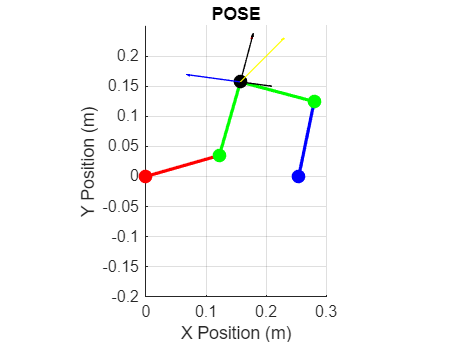


if error ==0
    plot_pose(t_a1,t_a2,t_p1,t_p2)
    
else
    error
end